# 繪圖軟體應用 第16周(12/25)

# M_Map

help m_map

  m_map - mapping toolbox (Author: rich@eos.ubc.ca)
  Version 1.4k  March 2019
 
  You have collected your data, loaded it into Matlab, analyzed 
  everything to death, and now you want to make a simple map showing 
  how it relates to the world. 
 
  But you can't. 
 
  Instead you have to figure out how to save all your data, and 
  then read it into a mapping program, and then spend all that extra 
  time figuring out why the mapping program doesn't give you what
  you expected it would...
 
  No more! 
 
                             Announcing M_Map v1.4! 
 
  M_Map is a set of mapping tools written for Matlab v5. These include: 
 
     1. Routines to project data in 18 different spherical 
        projections (and determine inverse mappings) 
     2. A grid generation routine to make nice axes with 
        limits either in long/lat terms or in planar
        X/Y terms. 
     3. A coastline database (with 1/4 degree resolution) 
     4. A global ele

- **Drawing tracklines 畫出航跡線**

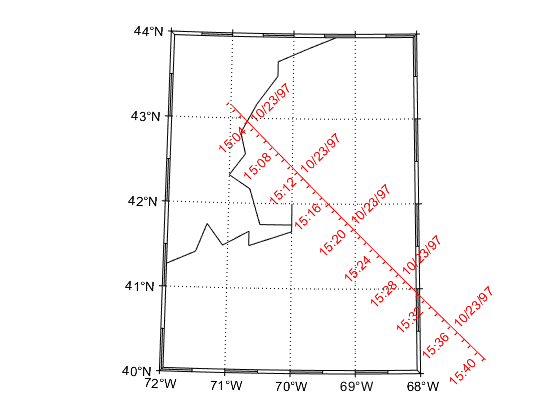

clear;clc
m_proj('UTM','long',[-72 -68],'lat',[40 44]);
m_coast('color','k');
m_grid('box','fancy','tickdir','out');
  
% fake up a trackline
lons=[-71:.1:-67];
lats=60*cos((lons+115)*pi/180);
dates=datenum(1997,10,23,15,1:41,zeros(1,41));
  
m_track(lons,lats,dates,'ticks',0,'times',4,'dates',8,...
    'clip','off','color','r','orient','upright'); 

% m_ungrid track

- **Drawing range rings and geodesics**

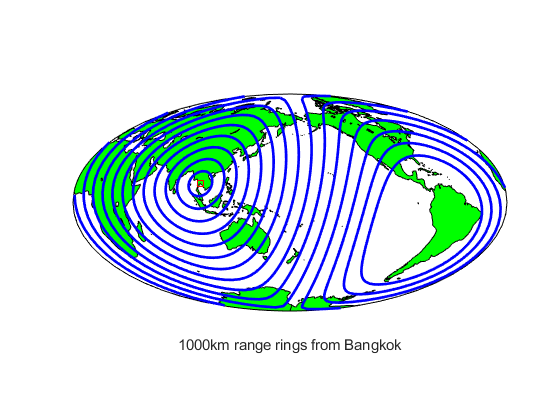

clf
m_proj('hammer','clong',170);
m_grid('xtick',[],'ytick',[],'linestyle','-');
m_coast('patch','g');
m_line(100.5,13.5,'marker','square','color','r');
m_range_ring(100.5,13.5,[1000:1000:15000],'color','b','linewi',2);
%從經緯(100.5,13.5)每1000公里畫一條線。畫到15000公里為止
xlabel('1000km range rings from Bangkok');

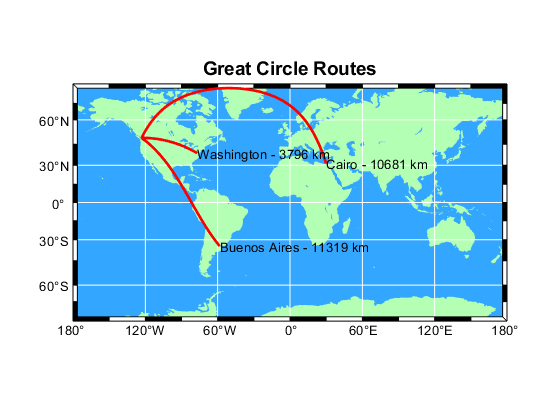

clf
m_proj('miller','lat',[-77 77]);   
m_coast('patch',[.7 1 .7],'edgecolor','none'); 
m_grid('box','fancy','linestyle','-','gridcolor','w','backcolor',[.2 .65 1]);
    
cities={'Cairo','Washington','Buenos Aires'}; 
lons=[ 30+2/60  -77-2/60   -58-22/60];
lats=[ 31+21/60  38+53/60  -34-45/60]; 
for k=1:3
%     [range,ln,lt]=m_lldist([121 lons(k)],[23.5  lats(k)],40); 
  [range,ln,lt]=m_lldist([-123-6/60 lons(k)],[49+13/60  lats(k)],40); 
  m_line(ln,lt,'color','r','linewi',2); 
  m_text(ln(end),lt(end),sprintf('%s - %d km',cities{k},round(range)));
end;
title('Great Circle Routes','fontsize',14,'fontweight','bold');

set(gcf,'color','w');   % Need to do this otherwise 'print' turns the lakes black

- **Colour and Colourmaps**

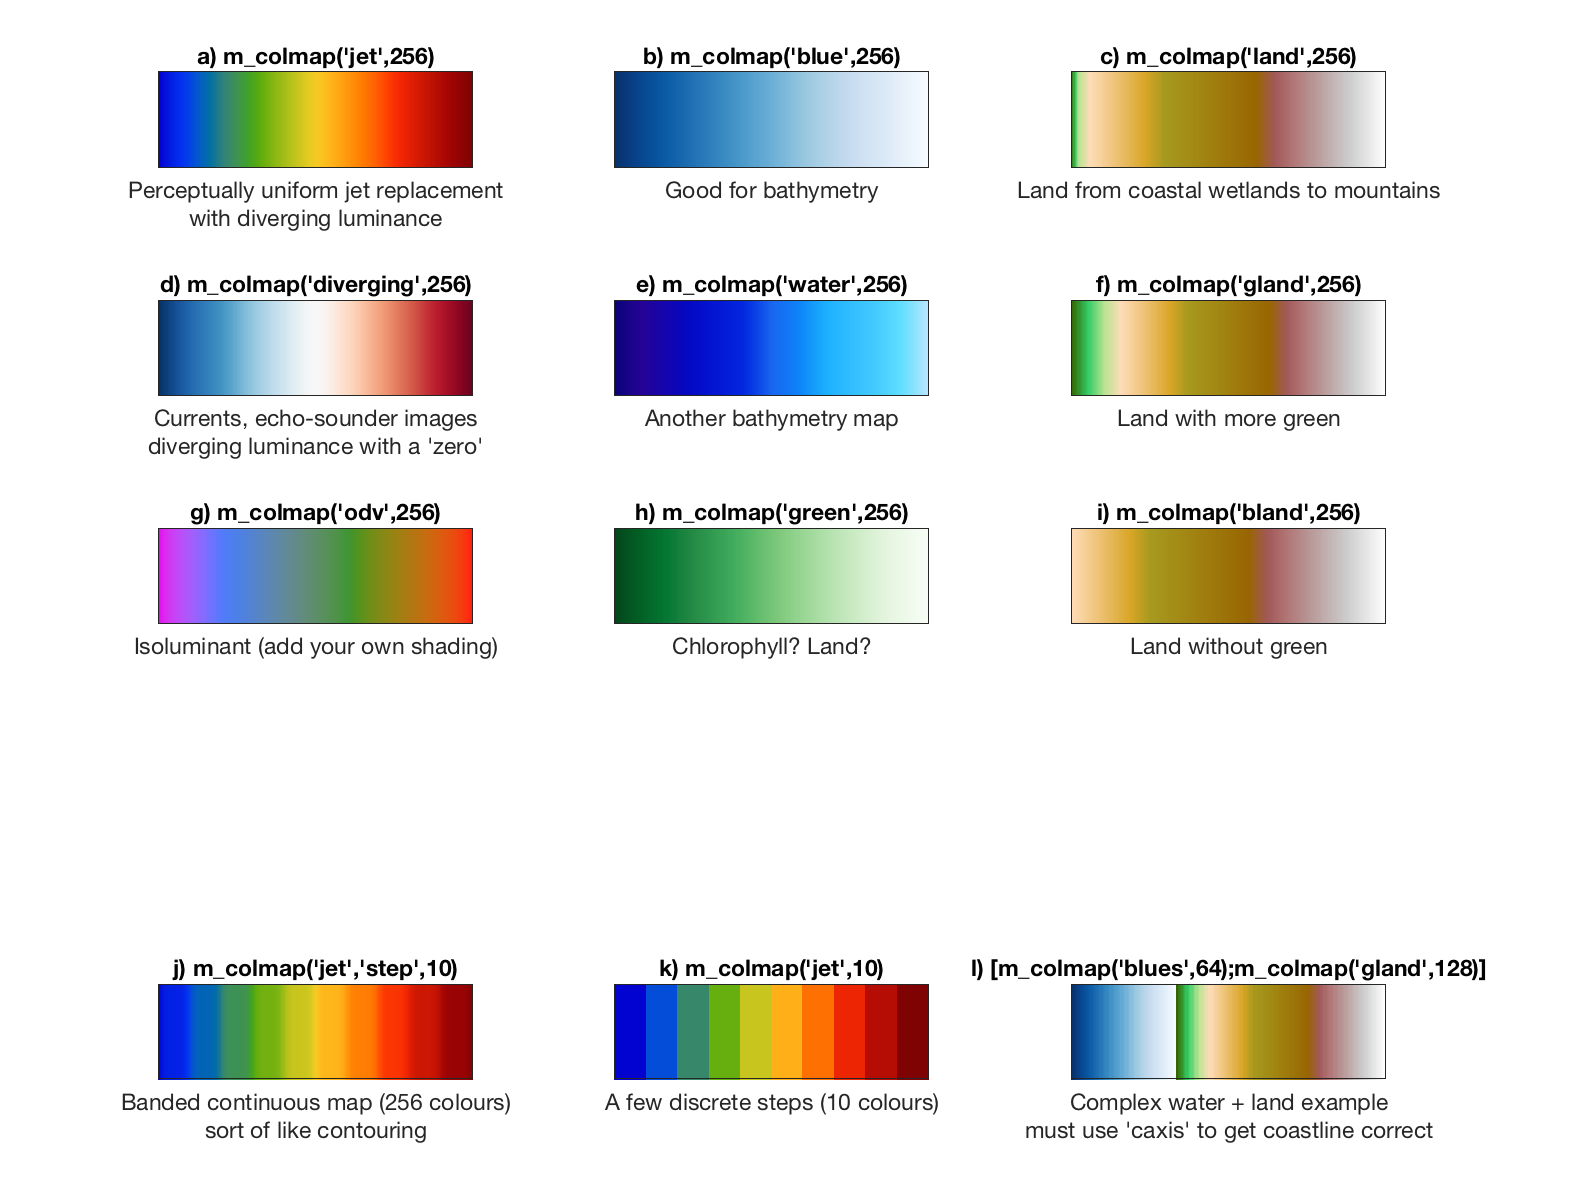

- **Colourbars with Contourmaps**

## 7. Removing features from a map

%nothing
%skip

## 8. Adding your own coastlines

**Reading and Handling coastline data**

If you have data is stored in 2 columns (longitudes then latitudes, with line segments separated by a row of NaNs) in a file named "coast.dat", you can plot it (as lines) using the following:

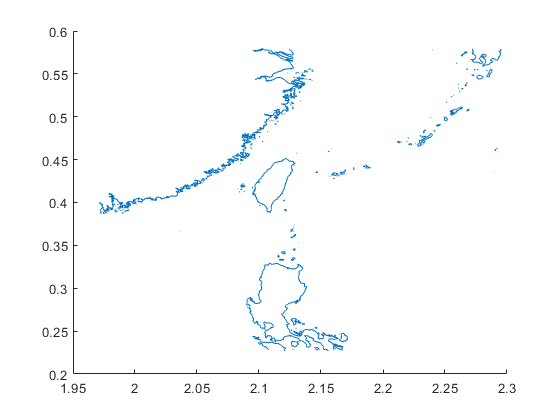

clf
load taiwan_coast.dat
m_line(taiwan_coast(:,1),taiwan_coast(:,2));

Filled coastlines will require more work. First, if the coastline is in a number of discrete segments, you have to join them all together to make complete "islands" and "lakes". If you are lucky, (i.e. no lakes or anything else), you *may* achieve success with

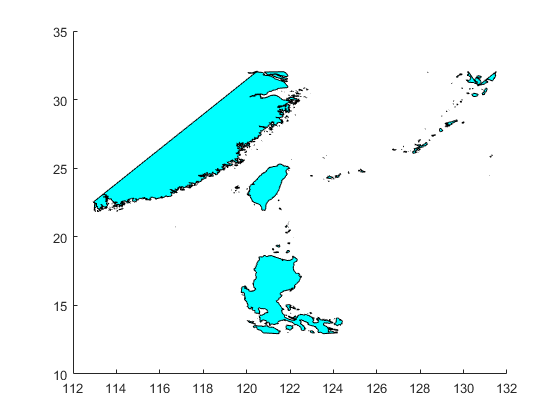

clear;clc;clf
load taiwan_coast.dat
[X,Y]=m_ll2xy(taiwan_coast(:,1),taiwan_coast(:,2),'clip','patch');
k=[find(isnan(X(:,1)))];
for i=1:length(k)-1
     x=taiwan_coast([k(i)+1:(k(i+1)-1) k(i)+1],1);
     y=taiwan_coast([k(i)+1:(k(i+1)-1) k(i)+1],2);
     patch(x,y,'c');
end;

and then try replacing `patch` with `m_patch`.

- [**GSHHS**](http://www.ngdc.noaa.gov/mgg/shorelines/gshhs.html)**(G) high-resolution coastline database**

%                      'c'  crude

%                      'l'  low

%                      'i'  intermediate

%                      'h'  high

%                      'f'  full

clf
help m_gshhs_i

  m_gshhs_i Add a coastline to a given map using the 'intermediate' resolution of
            the Global Self-consistant Hierarchical High-resolution 
            Shorelines.
 
          m_gshhs_i( (standard line option,...,...) ) draws the coastline
          as a simple line.
          m_gshhs_i('patch' ( ,standard patch options,...,...) ) draws the 
          coastline as a number of patches. 
 
          m_gshhs_i('save',FILENAME) saves the extracted coastline data
          for the current projection in a file FILENAME. This allows 
          speedier replotting using M_USERCOAST(FILENAME). 
     
          See also m_proj, m_grid, m_coast, m_gshhs_l, m_gshhs_h, m_gshhs_c 
          

m_proj('Mercator','lon',[100 140],'lat',[10 40])
m_gshhs_i('patch','g');

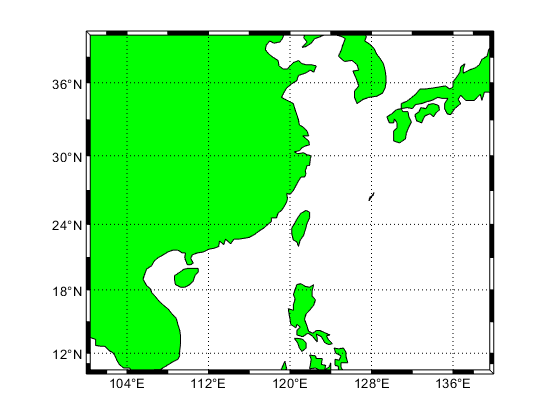

m_grid('box','fancy')

## Example Code

[https://www.eoas.ubc.ca/~rich/map.html#examples](https://www.eoas.ubc.ca/~rich/map.html#examples)

**1. M_Map Logo**

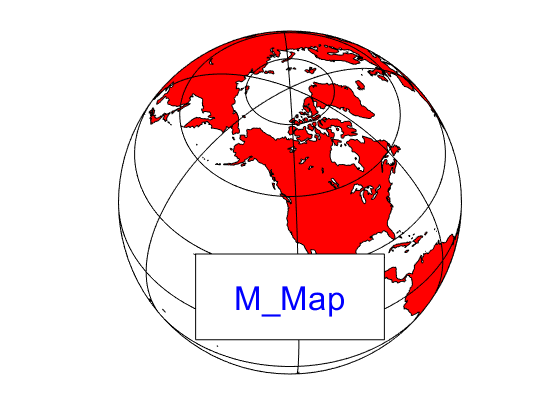

clf
m_proj('ortho','lat',48','long',-123');
m_coast('patch','r');
m_grid('linest','-','xticklabels',[],'yticklabels',[]);

patch(.55*[-1 1 1 -1],.25*[-1 -1 1 1]-.55,'w'); 
text(0,-.55,'M\_Map','fontsize',25,'color','b',...
    'verticalalignment','middle','horizontalalignment','center');

**5. Oblique Mercator Projection with quiver and contour data**

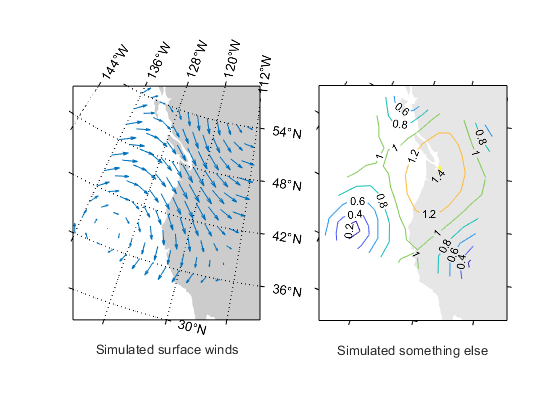

clf
%% Nice looking data
[lon,lat]=meshgrid([-136:2:-114],[36:2:54]);
u=sin(lat/6);
v=sin(lon/6);

m_proj('oblique','lat',[56 30],'lon',[-132 -120],'aspect',.8);
subplot(121);
m_coast('patch',[.8 .8 .8],'edgecolor','none');
m_grid('tickdir','out','yaxislocation','right',...
            'xaxislocation','top','xlabeldir','end','ticklen',.02);
hold on;
m_quiver(lon,lat,u,v);
xlabel('Simulated surface winds');
subplot(122);
m_coast('patch',[.9 .9 .9],'edgecolor','none');
m_grid('tickdir','out','yticklabels',[],...
              'xticklabels',[],'linestyle','none','ticklen',.02);
hold on;
[cs,h]=m_contour(lon,lat,sqrt(u.*u+v.*v));
clabel(cs,h,'fontsize',8);
xlabel('Simulated something else');

**6. Miller Projection with Great Circle**

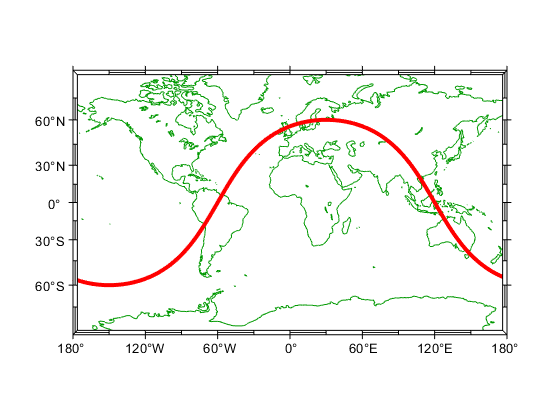

clear;clc;clf
% Plot a circular orbit
lon=[-180:180];
lat=atan(tan(60*pi/180)*cos((lon-30)*pi/180))*180/pi;
m_proj('miller','lat',82);
m_coast('color',[0 .6 0]);
m_line(lon,lat,'linewi',3,'color','r');
m_grid('linestyle','none','box','fancy','tickdir','out');

**9. Zoom in on Prince Edward Island to show different coastline resolutions**

% Example showing the default coastline and all of the different resolutions
% of GSHHS coastlines as we zoom in on a section of Prince Edward Island.

clear;clf
axes('position',[.35 .6 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[40 60],'long',[-90 -50],'rect','on');
m_coast('patch',[0 1 0]);
m_grid('linestyle','none','linewidth',2,'tickdir','out',...
       'xaxisloc','top','yaxisloc','right','fontsize',6);
m_text(-69,51,'Standard coastline','color','r','fontweight','bold');
m_ruler([.5 .9],.8,3,'fontsize',8)

axes('position',[.09 .5 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[40 54],'long',[-80 -55],'rect','on');
m_gshhs_c('patch',[.2 .8 .2]);

m_grid('linestyle','none','linewidth',2,'tickdir','out',...
       'xaxisloc','top','fontsize',6);
m_text(-80,52.5,'GSHHS\_C (crude)','color','m','fontweight','bold');
m_ruler([.5 .9],.8,2,'fontsize',8);
  
axes('position',[.13 .2 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[43 48],'long',[-67 -58],'rect','on');
m_gshhs_l('patch',[.4 .6 .4]);

m_grid('linestyle','none','linewidth',2,'tickdir','out','fontsize',6);
m_text(-66.5,43.5,'GSHHS\_L (low)','color','m','fontweight','bold');
m_ruler([.5 .9],.8,3,'fontsize',8);
 
axes('position',[.35 .05 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[45.8 47.2],'long',[-64.5 -62],'rect','on');
m_gshhs_i('patch',[.5 .6 .5]);

m_grid('linestyle','none','linewidth',2,'tickdir','out',...
       'yaxisloc','right','fontsize',6);
m_text(-64.4,45.9,'GSHHS\_I (intermediate)   ','color','m',...
      'fontweight','bold','horizontalalignment','right');
m_ruler([.5 .8],.1,3,'fontsize',8);
 
axes('position',[.5 .1 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[46.375 46.6],'long',[-64.2 -63.7],'rect','on');
m_gshhs_h('patch',[.6 .7 .6]);

m_grid('linestyle','none','linewidth',2,'tickdir','out',...
       'xaxisloc','top','yaxisloc','right','fontsize',6);
m_text(-64.18,46.4,'GSHHS\_H (high)','color','m','fontweight','bold');
m_ruler([.5 .8],.2,3,'fontsize',8);
 
axes('position',[.55 .35 .37 .37]); %畫圖中圖
m_proj('albers equal-area','lat',[46.55 46.65],'long',[-63.97 -63.77],'rect','on');
m_gshhs_f('patch',[.7 .9 .7]);

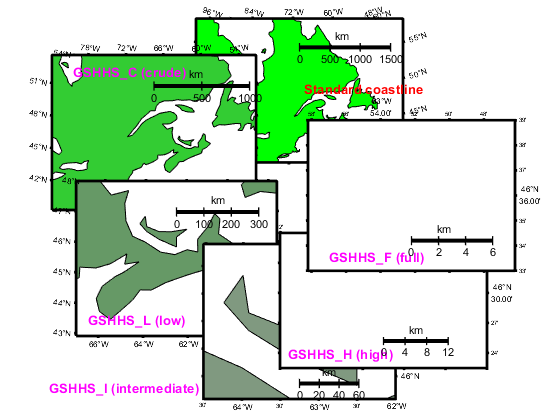

m_grid('linestyle','none','linewidth',2,'tickdir','out',...
       'xaxisloc','top','yaxisloc','right','fontsize',6);
m_text(-63.95,46.56,'GSHHS\_F (full)','color','m','fontweight','bold');
m_ruler([.5 .8],.2,3,'fontsize',8);


%toolbox裡沒有m_map，會出現警告訊息

**14. One Ocean Projection**

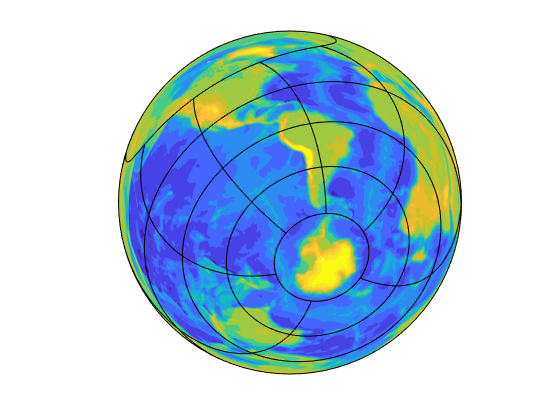

%  This projection shows all the oceans connected to each other - the outside ring
%  is the Asian coastline (Thanks to M B-O for this idea)
% otherwise its just an example of different map types.
clear;clc;clf

m_proj('azimuthal equal-area','radius',156,'lat',-46,'long',-95,'rot',30);
m_elev('contourf',[-7000:1000:0 500:500:3000],'edgecolor','none');
% colormap(ax2,[m_colmap('blues',70);m_colmap('gland',30)]);  
% caxis(ax2,[-7000 3000]);       
m_grid('xticklabel',[],'yticklabel',[],'linestyle','-','ytick',[-60:30:60]);

## Examples of satellite data manipulation

**1. Global SST (or any variable on a global Lat/Long grid)**

[https://podaac.jpl.nasa.gov/SeaSurfaceTemperature](https://podaac.jpl.nasa.gov/SeaSurfaceTemperature)

clear;clc;clf
% % NOAA/NASA Pathfinder AVHRR SST product
% % http://podaac.jpl.nasa.gov/sst/
% 
% [P,map]=imread('../m_mapWK/199911h54ma-gdm.hdf');
% 
% % Documentation for the 54km dataset gives
% % this formula for temperature
% P=0.15*double(P)-3; % deg C
% 
% %...and defines this Lat/Long grid for the data
% Plat=90-.25-[0:359]*.5;Plon=-180+.25+[0:719]*.5;
% 
% % Since the grid is rectangular in lat/long (i.e. not
% % really a projection at all, although it is included in
% % m_map under the name 'equidistant cyldindrical'), we 
% % don't want to use the 'image' technique. Instead... 
% % Create a grid, offsetting by half a grid point to account
% % for the flat pcolor
% [Plg,Plt]=meshgrid(Plon-0.25,Plat+0.25);
% 
% m_proj('hammer-aitoff','clongitude',-150);
% 
% % Rather than rearranging the data so its limits match the
% % plot I just draw it twice (you can see the join at 180W
% % because of the quirks of flat pcolor) (Note that 
% % all the global projections have 360 deg ambiguities)
% m_pcolor(Plg,Plt,P);shading flat;colormap(map);
% hold on;
% m_pcolor(Plg-360,Plt,P);shading flat;colormap(map);
% 
% m_coast('patch',[.6 1 .6]);
% m_grid('xaxis','middle');
% 
% % add a standard colorbar.
% h=colorbar('h');
% set(get(h,'xlabel'),'string','AVHRR SST Nov 1999');
% 

**5. Meteorological data (netCDF format)**

% clear;clf
% iday=156;   % the day to show
% 
% % use ncdisp(filename) to discover file contents...
% 
% lat=ncread('uwnd.10m.gauss.2017.nc','lat');
% lon=ncread('uwnd.10m.gauss.2017.nc','lon');
% [LN,LT]=meshgrid(lon,lat);
% 
% mtime=ncread('uwnd.10m.gauss.2017.nc','time')/24+datenum(1800,1,1,0,0,0);
% u=ncread('uwnd.10m.gauss.2017.nc','uwnd',[1,1,iday],[192,94,1]);
% v=ncread('vwnd.10m.gauss.2017.nc','vwnd',[1,1,iday],[192,94,1]);
% prate=ncread('prate.sfc.gauss.2017.nc','prate',[1,1,iday],[192,94,1]);
% 
% m_proj('miller','lon',[100 260],'lat',[0 65]);
% m_coast('patch',[.8 .8 .8]);
% hold on 
% [CS,CH]=m_contourf(LN,LT,prate'*1e3,[0.05:.05:.7],'edgecolor','none');
% m_windbarb(LN,LT,u' ,v',2,'units','m/s','linewi',1,'color','r');
% hold off;
% m_grid('box','fancy','tickdir','out');
% 
% ax=m_contfbar([.3 .7],.05,CS,CH);
% set(ax,'fontsize',12)
% xlabel(ax,'Mean Daily Precipitation Rate/(kg/m^2/s)');
% 
% title(['North Pacific Surface Winds : ' datestr(mtime(iday))],'fontsize',16);
% 
% colormap(flipud(m_colmap('Blues')))

**6. ARGO drifter tracks (netCDF format)**

**7. SAR image of internal waves (HDF-5 format)**